# entropic Flux Balance Analysis (eFBA)

Author : Samira Ranjbar

In the context of FBA, an objective function is a mathematical representation of a cellular process that the model attempts to optimize. In eFBA, the objective function aims to maximize the Shannon entropy of the flux distribution, subject to constraints ensuring the feasibility and thermodynamic consistency of the fluxes. Shannon entropy measures the degree of disorder or randomness in a system. In entropic Flux Balance Analysis, maximizing the Shannon entropy of the flux distribution corresponds to identifying the flux distribution that is the most flexible and least structured, given the constraints imposed by the metabolic network and thermodynamic laws. This approach is valuable because it captures the metabolic network’s flexibility, crucial for understanding how cells adapt to changing environmental conditions.

**Toy model**

reactionFormulas = {'4 A  -> 4 B',...
    '2 A  -> 2 B',...
    'A  -> B',...
    'A  <=> ',...
    'B  <=> '};
reactionNames = {'R1', 'R2', 'R3', 'R4', 'R5'};
lowerBounds = [  -10,   -10,   -10, -10, 10];
upperBounds = [ 10,  10,  10, -10, 10];
model = createModel(reactionNames, reactionNames, reactionFormulas,...
                             'lowerBoundList', lowerBounds, 'upperBoundList', upperBounds);        

Adding the following Metabolites to the model:
A[c]
B[c]
addMultipleReactions: Adding the following reactions to the model:
R1	4 A[c] 	<=>	4 B[c] 
R2	2 A[c] 	<=>	2 B[c] 
R3	A[c] 	<=>	B[c] 
R4	A[c] 	<=>	
R5	B[c] 	->	


 initCobraToolbox;



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.25.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

 FBAsolution = optimizeCbModel(model,'max'); 

The flux distribution is shown in figure 1:

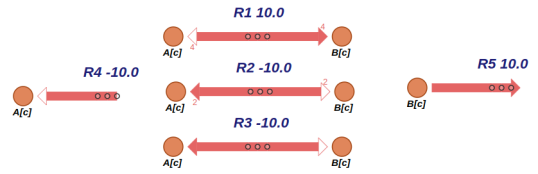

Figure1: Flux distribution calculated using FBA in model1.

As you can see, reactions 'R1' and 'R2' or 'R1' and 'R3' have created a cycle within the network. A cycle means the system is not following the laws of thermodynamics and, therefore, is not occurring in reality. lets look at eFBA results:

param.solver = 'mosek';
param = mosekParamSetEFBA(param);
[solution,~] = entropicFluxBalanceAnalysis(model,param);

And illustration using escher is shown in figure2:

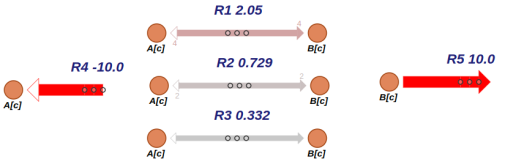

Figure2: Flux distribution calculated using eFBA in model1.



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.25.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

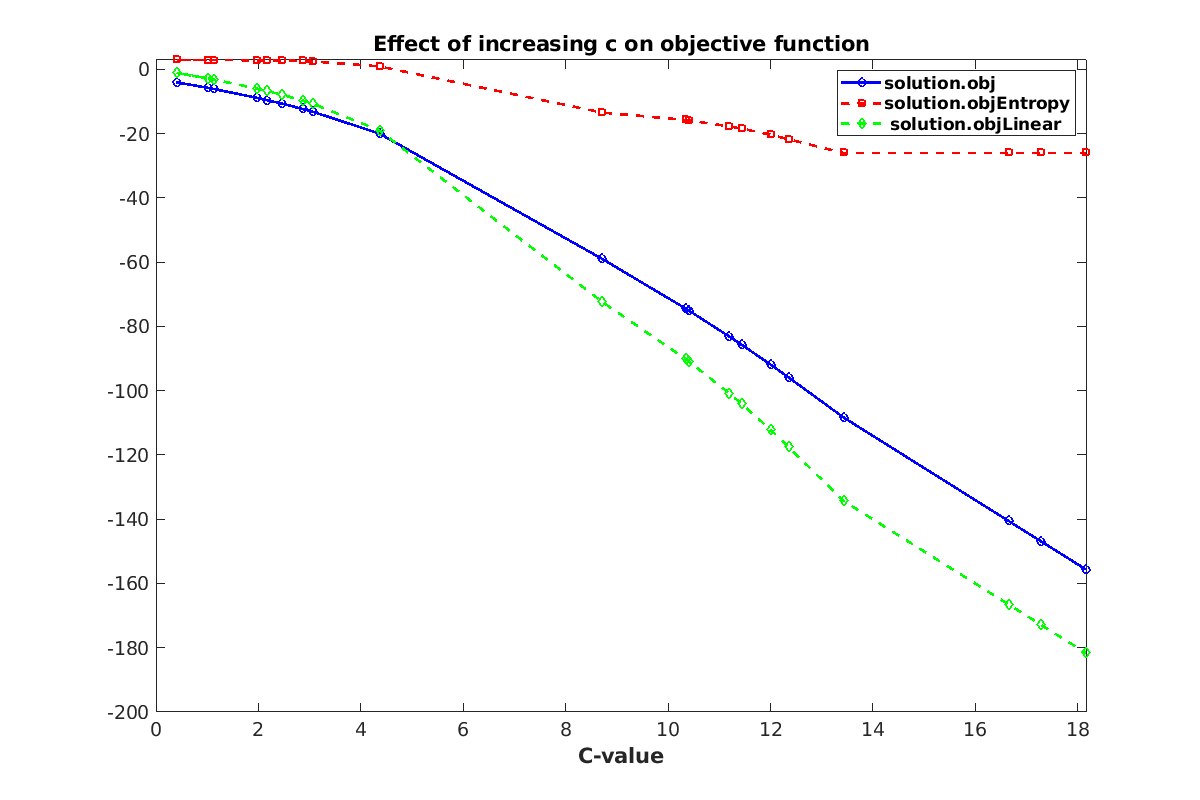

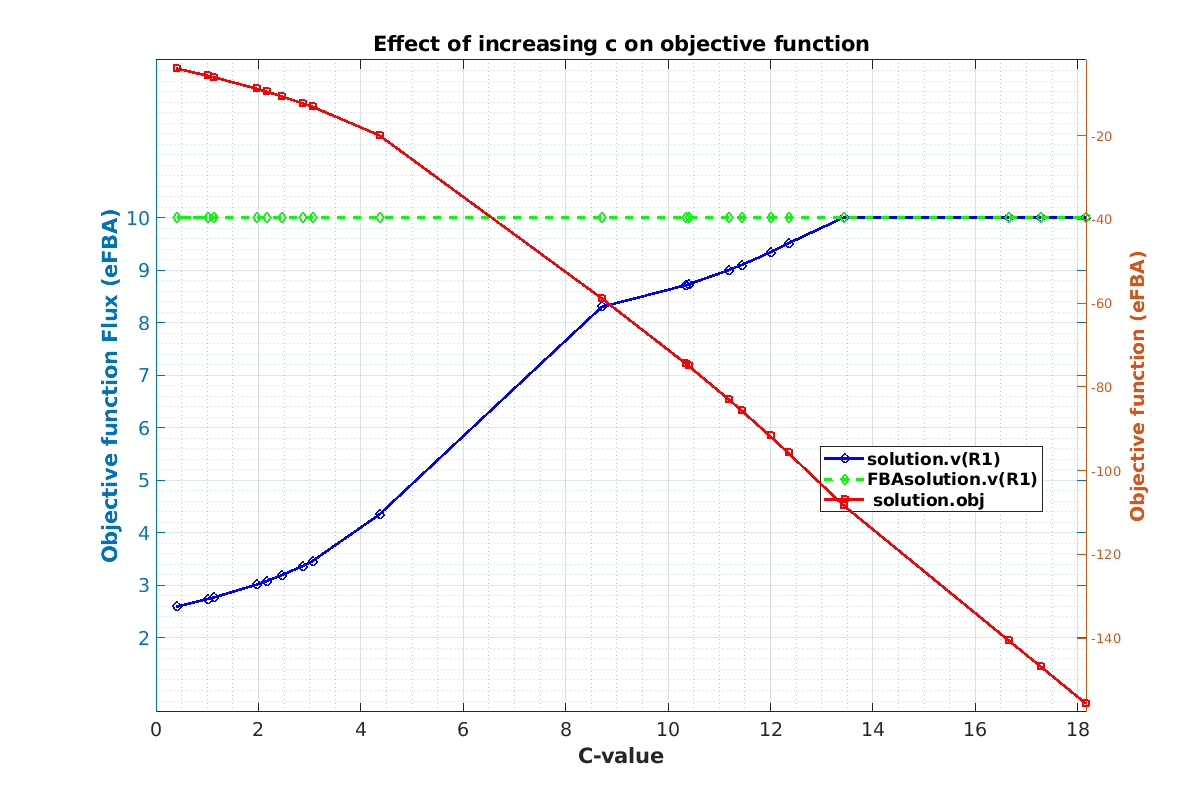

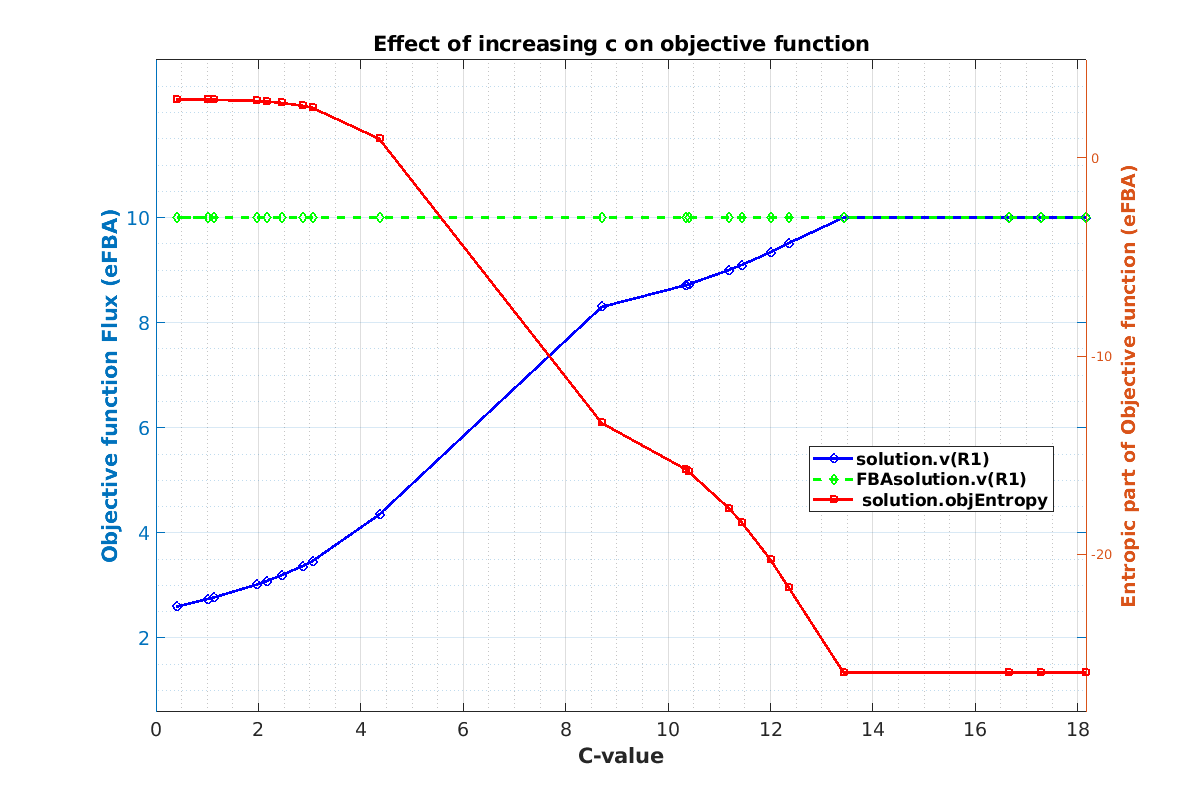

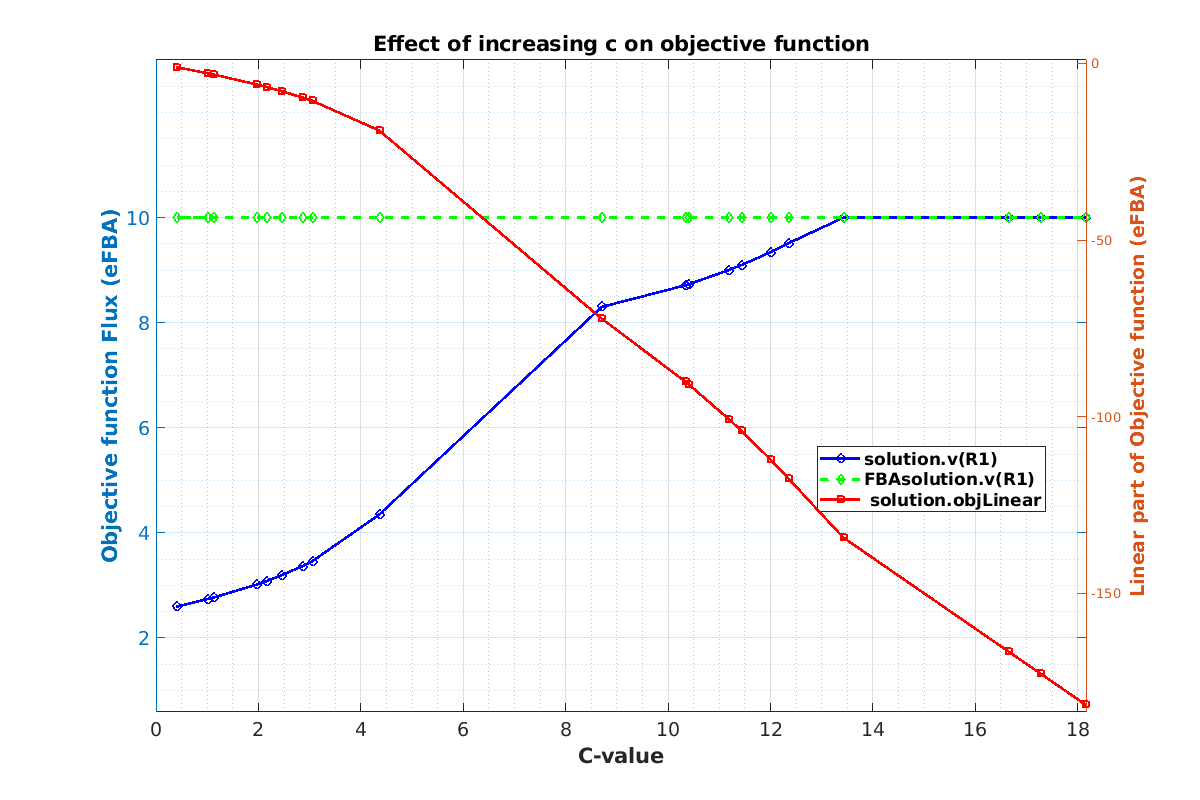

plotyy_eFBA(model,'R1',20,20,1);

Use **tmorous mesenchymal** as an example:

clear all
warning('off', 'all')
load('~/drive/glioblastoma/results/csf_media/defaultModels/absolute/-2/TCmesnh/scRecon3D_mesnh.mat')
 model = scRecon3D_mesnh;
 param.solver = 'mosek';
param = mosekParamSetEFBA(param);
[solution,~] = entropicFluxBalanceAnalysis(model,param);

Using existing internal net flux bounds without modification.

MOSEK Version 10.1.15 (Build date: 2023-10-12 20:25:19)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 3821            
  Affine conic cons.     : 4532 (13596 rows)
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 9329            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1               



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.25.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

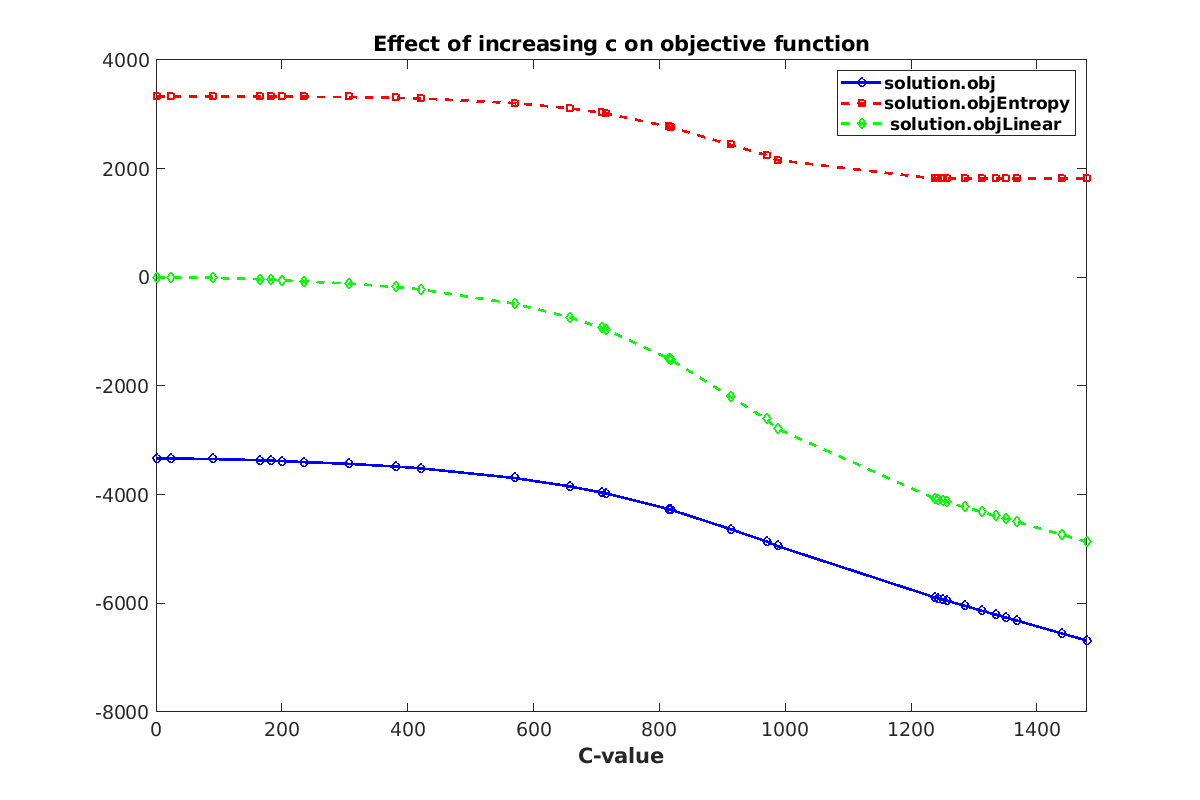

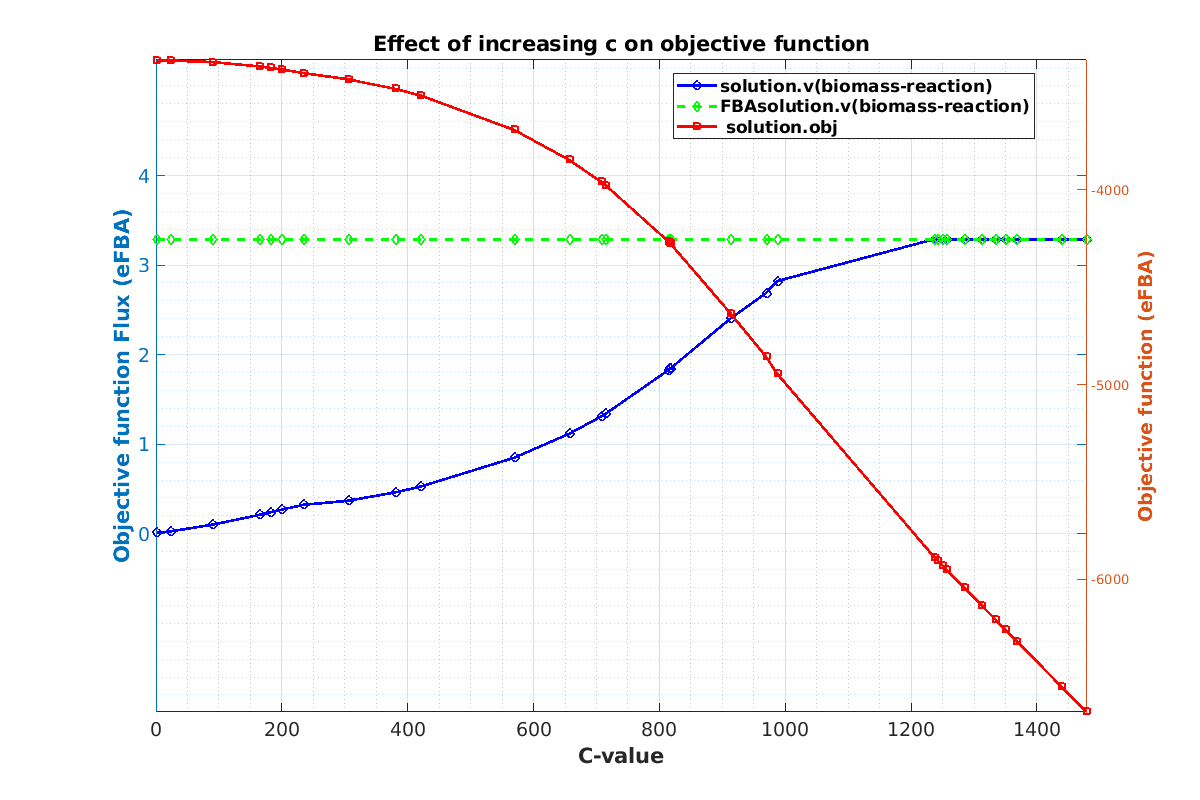

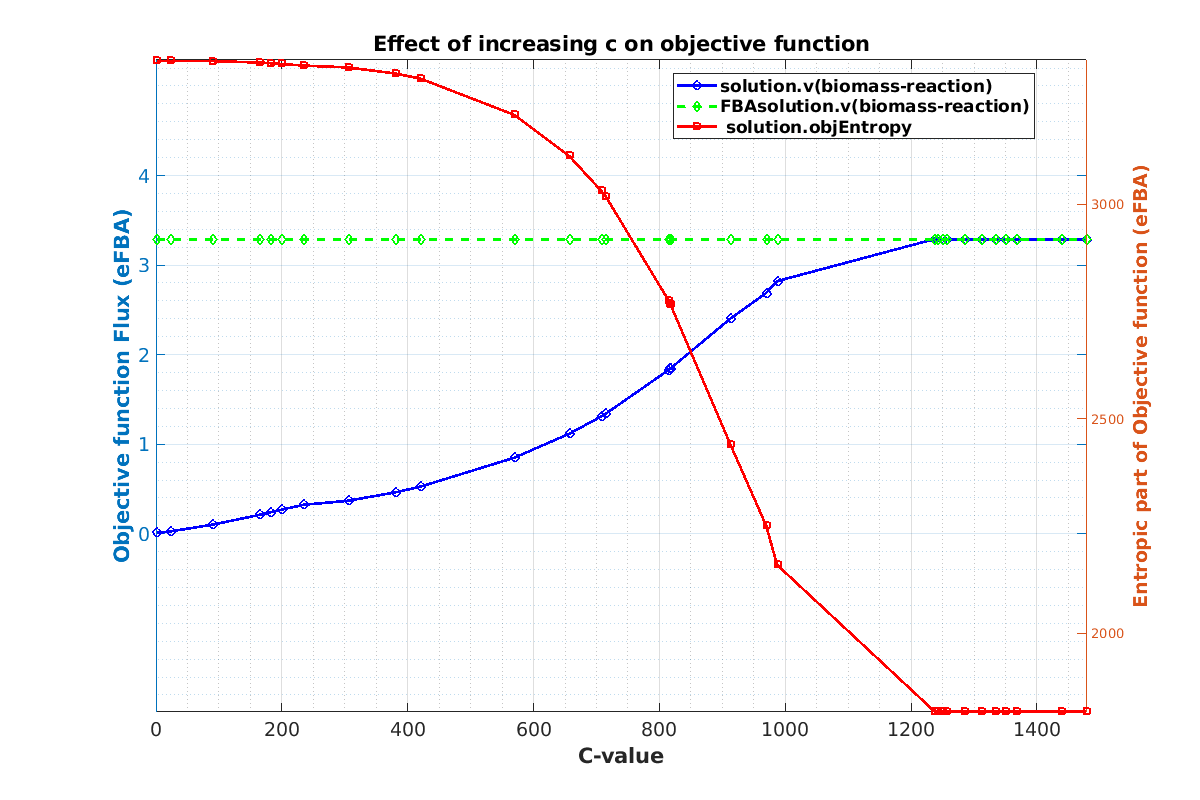

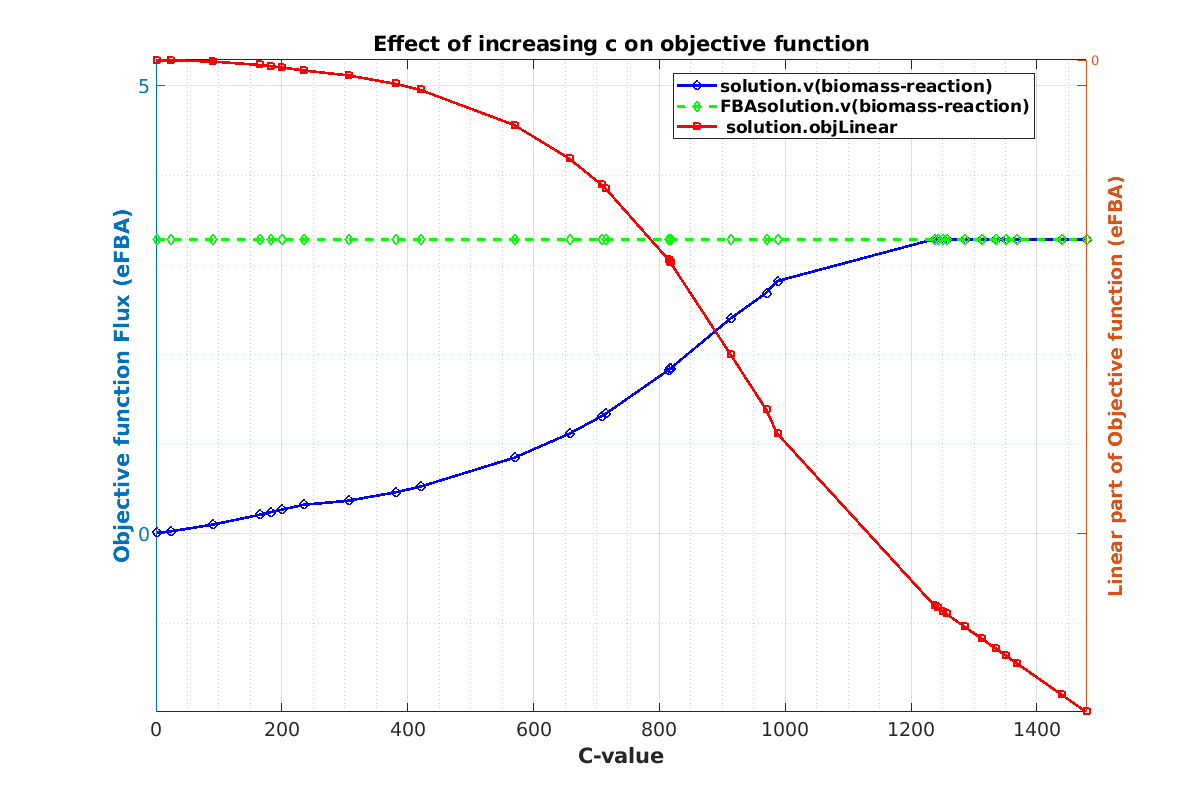

plotyy_eFBA(model,'biomass_reaction',1500,30,0);

## **Estimation of C (coefficient of objective function)**

After understanding the behavior of flux in the objective function as a function of C, the question becomes: which value of C is the best for modeling? The value of flux changes between zero and the maximum value calculated in FBA. The C at the maximum value is not the best, since our model will never meet that value. It is important to know what is expected from the model in reality. The answer to this question comes from experiments. For example, in the case of biomass, we know that the growth rate is related to doubling time according to the equation below. If we know the doubling time of the cell, we can find the C value corresponding to that value in modeling.

clear all
 warning('off', 'all')
load('~/drive/glioblastoma/results/csf_media/defaultModels/absolute/-2/TCmesnh/scRecon3D_mesnh.mat');
model = scRecon3D_mesnh;

solution_vals(:,1) = 0:50:1400;
param.printLevel = 0;
param.solver = 'mosek';
%model
initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.25.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

FBAsolution = optimizeCbModel(model,'max');
for nr = 1:length(solution_vals)
    model.c(ismember(model.rxns, 'biomass_reaction')) = solution_vals(nr,1);
    [solution,~] = entropicFluxBalanceAnalysis(model,param);
    solution_vals(nr,2) = solution.v(ismember(model.rxns, 'biomass_reaction'));
end

sub_solution_vals(:,1) = 0:0.1:15;
param.printLevel = 0;
for nr = 1:length(sub_solution_vals)
    model.c(ismember(model.rxns, 'biomass_reaction')) = sub_solution_vals(nr,1);
    [solution,~] = entropicFluxBalanceAnalysis(model,param);
    sub_solution_vals(nr,2) = solution.v(ismember(model.rxns, 'biomass_reaction'));
end

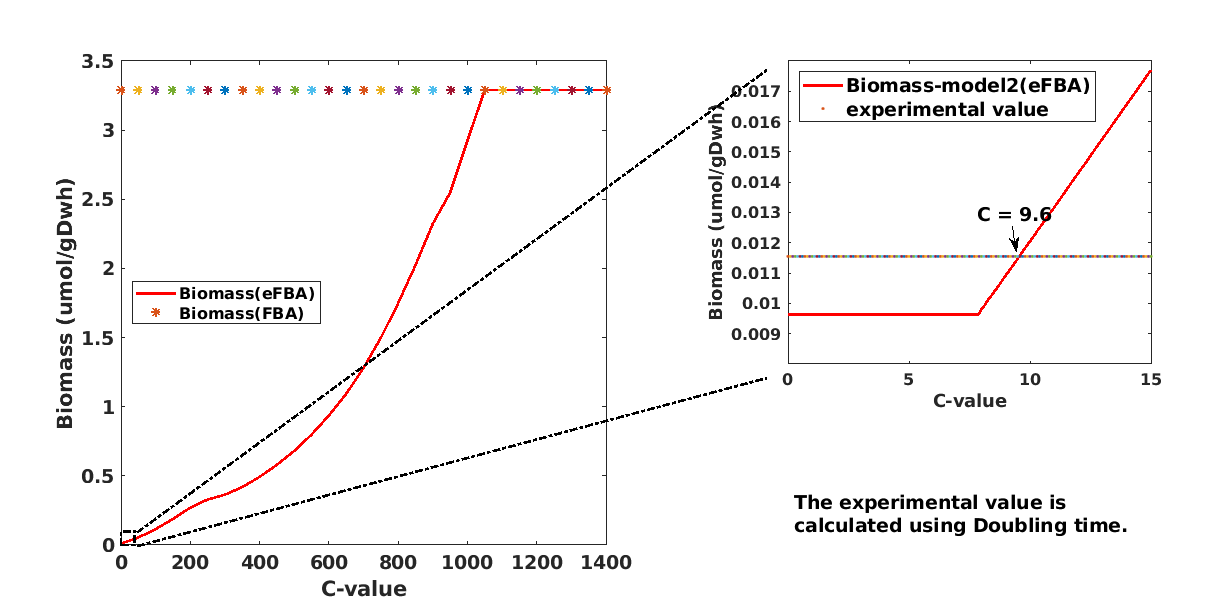

figure('Renderer', 'painters', 'Position', [10 10 1600 800]);
% Define subplot positions
pos1 = [0.1, 0.1, 0.4, 0.8];  % [left, bottom, width, height]
pos2 = [0.65, 0.4, 0.30, 0.5];  % [left, bottom, width, height]
experimental_value = log(2)/60; % it is an example in case that doubling time is considered to be 600 hourse
% Subplot 1
subplot('Position', pos1);
plot(solution_vals(:,1), solution_vals(:,2), 'red', ...
solution_vals(:,1), FBAsolution.f, '*', 'LineWidth', 2);

legend('Biomass(eFBA)','Biomass(FBA)',"FontSize",12, 'Location', 'West')
ylabel('Biomass (umol/gDwh)', "FontSize",14, "FontWeight","bold");
xlabel('C-value', "FontSize",14, "FontWeight","bold");
xlim([0 max(solution_vals(:,1))])
rectangle('Position', [0, 0, 40, 0.1], 'EdgeColor', 'black', 'LineWidth', 2,'LineStyle','-.');

% Draw lines from rectangle to the next subplot
x1 = pos1(1) + pos1(3);
y1 = pos1(2) + pos1(4) / 2;
x2 = pos2(1);
y2 = pos2(2) + pos2(4) / 2;
set(gca, 'XTickLabel', get(gca, 'XTickLabel'), 'FontWeight', 'bold', 'FontSize', 14);

% Subplot 2
subplot('Position', pos2);
plot(sub_solution_vals(:,1), sub_solution_vals(:,2),'red',...
     sub_solution_vals(:,1),  experimental_value,'.', 'LineWidth',2)
legend('Biomass-model2(eFBA)','experimental value',"FontSize",14, 'Location',"NorthWest")
ylabel('Biomass (umol/gDwh)', "FontSize",14, "FontWeight","bold");
xlabel('C-value', "FontSize",14, "FontWeight","bold");
xlim([0 max(sub_solution_vals(:,1))])
% ylim([0.009 0.02])
% xticks(0:1:15);

%add crossing point box
[~,index] = min(abs(sub_solution_vals(:,2) - experimental_value));
% the closest intersection is:
[sub_solution_vals(index,1) experimental_value];
annotation("textarrow", [0.835 0.8385], [0.6263 0.5854], "String", ['C = ',num2str(sub_solution_vals(index,1))], 'FontWeight', 'bold', 'FontSize', 14)

% text
annotation('textbox', [pos2(1), 0.1, pos2(3), 0.1], 'String', ['The experimental value is calculated using Doubling time.'],...
    'HorizontalAlignment', 'left', 'VerticalAlignment','middle', 'FontWeight', 'bold', 'FontSize', 14,'EdgeColor', 'none');
set(gca, 'XTickLabel', get(gca, 'XTickLabel'), 'FontWeight', 'bold', 'FontSize', 12);
annotation("line", [0.113 0.6328], [0.1211 0.8845], 'Color', 'black', 'LineWidth', 2,'LineStyle','-.')
annotation("line", [0.113 0.6328], [0.09871 0.3762],'Color', 'black', 'LineWidth', 2,'LineStyle','-.')
% axes 1
% Property editing
positionPropObjs = findobj(gcf, "-property", "Position");
positionPropObjs(1).Position = [0 0 1212.0000, 606.0000];

**Putting weight on cr and cf to unbias transpot of massive molecules**

- **Using Mass**

All reactions that do not include an R-group are mass-balanced.


LeftNullSpace_nonzero = 1498

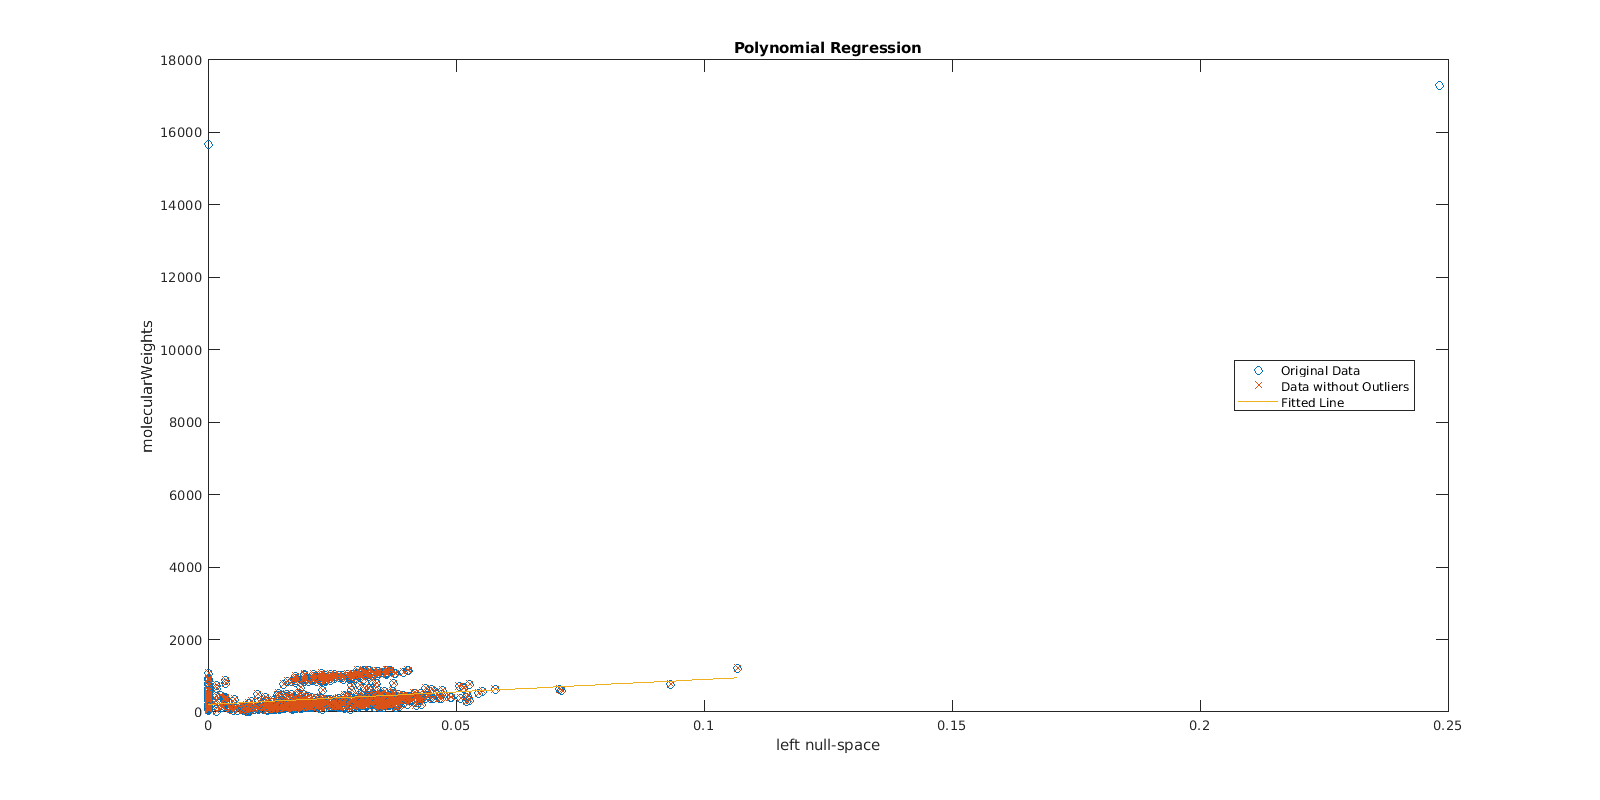

Fitted Polynomial Equation:
y = 6897.7526 * x^1 + 208.665


[substratesMass, productsMass] = calculateReactionMasses(model);

ave_mass = (substratesMass + productsMass) /2;
c_mass = ave_mass/ sum(ave_mass);% normalize to avoid too agressive results

**2. Using Gene expression**

T = readtable('~/drive/glioblastoma/data/input/csf_media/scRef_celltypeAvg.csv');
geneWeight=calculateGeneWeight(model,T(:,[2,51]), 0.1);

% check to put weight only on internal reactions
j =1;
for i = 1: numel(model.rxns)
    if model.SConsistentRxnBool(i)
       SCReactionWeight(i) = geneWeight(j);
       SCReactionMass(i) = c_mass(j);
       j = j+1;
    elseif ~model.SConsistentRxnBool(i)
        SCReactionWeight(i)= 0;
        SCReactionMass(i) = 0;
    end
end
c_gene = -log(SCReactionWeight + 1);
c_Mass = SCReactionMass ;

% weight on objective function
model.c(findRxnIDs(model, 'biomass_reaction')) = 9.6;%rec1
[solution,~] = entropicFluxBalanceAnalysis(model,param);
% changing cr and cf according to geneweight
model1 = model;
model1.cr = -log(SCReactionWeight + 1);%- min(-log(SCReactionWeight)));
model1.cf = -log(SCReactionWeight + 1); %- min(-log(SCReactionWeight)));

[solution1,~] = entropicFluxBalanceAnalysis(model1,param);
% changing cr and cf according to mass
model2 = model;
model2.cr = SCReactionMass;
model2.cf = SCReactionMass;

[solution2,~] = entropicFluxBalanceAnalysis(model2,param);

model3 = model;
model3.cr = model1.cr + model2.cr;
model3.cf = model1.cf + model2.cf;

[solution3,~] = entropicFluxBalanceAnalysis(model3,param);
% initCobraToolbox
FBAsolution = optimizeCbModel(model,'max');
FBAsolution1 = optimizeCbModel(model1,'max');
FBAsolution2 = optimizeCbModel(model2,'max');
FBAsolution3 = optimizeCbModel(model3,'max');

see the effect of weigtening on flux value in some subsystems:

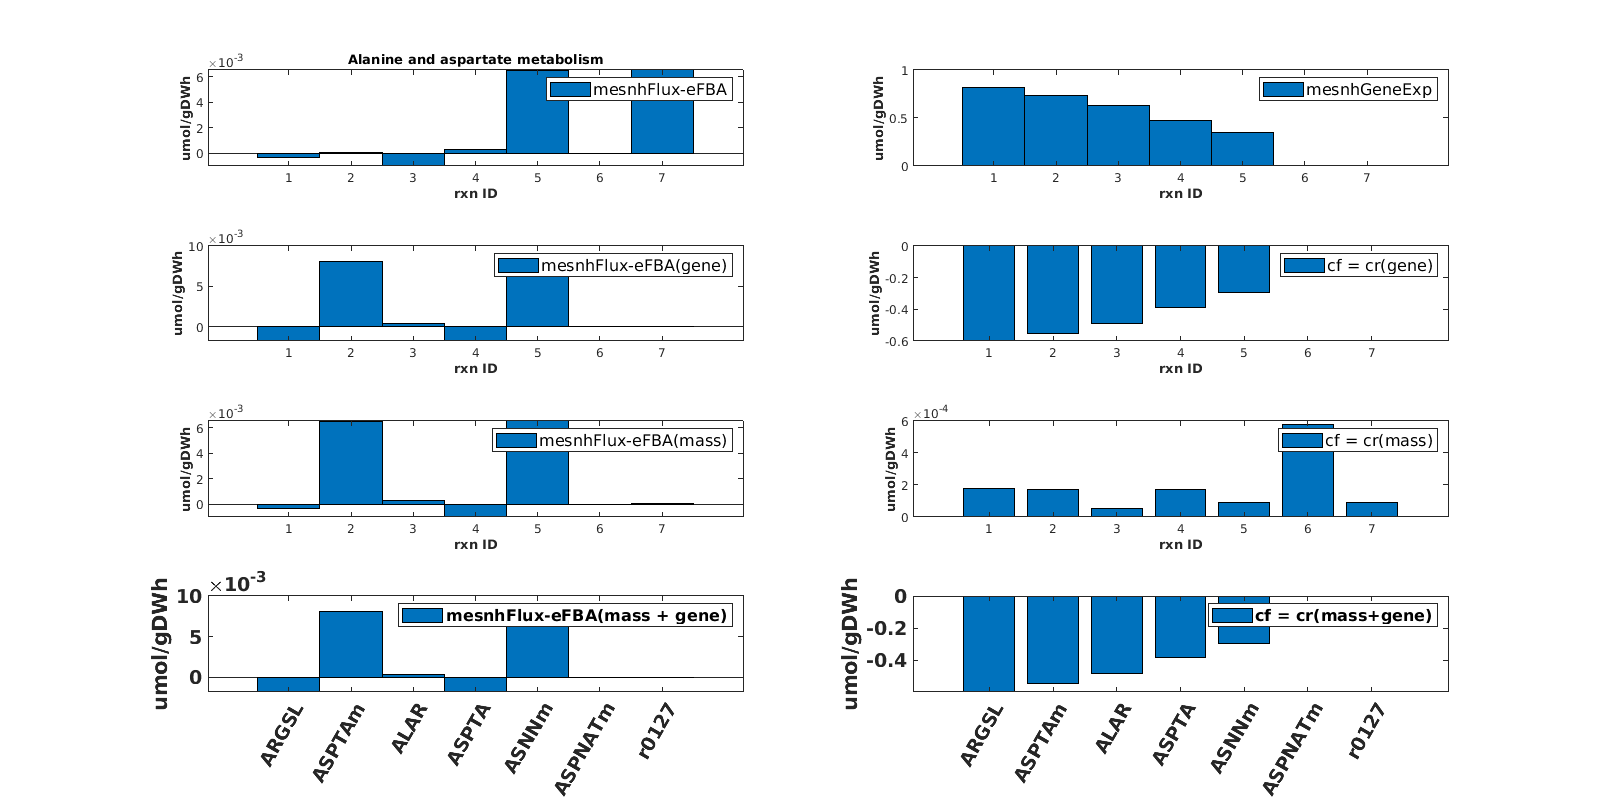

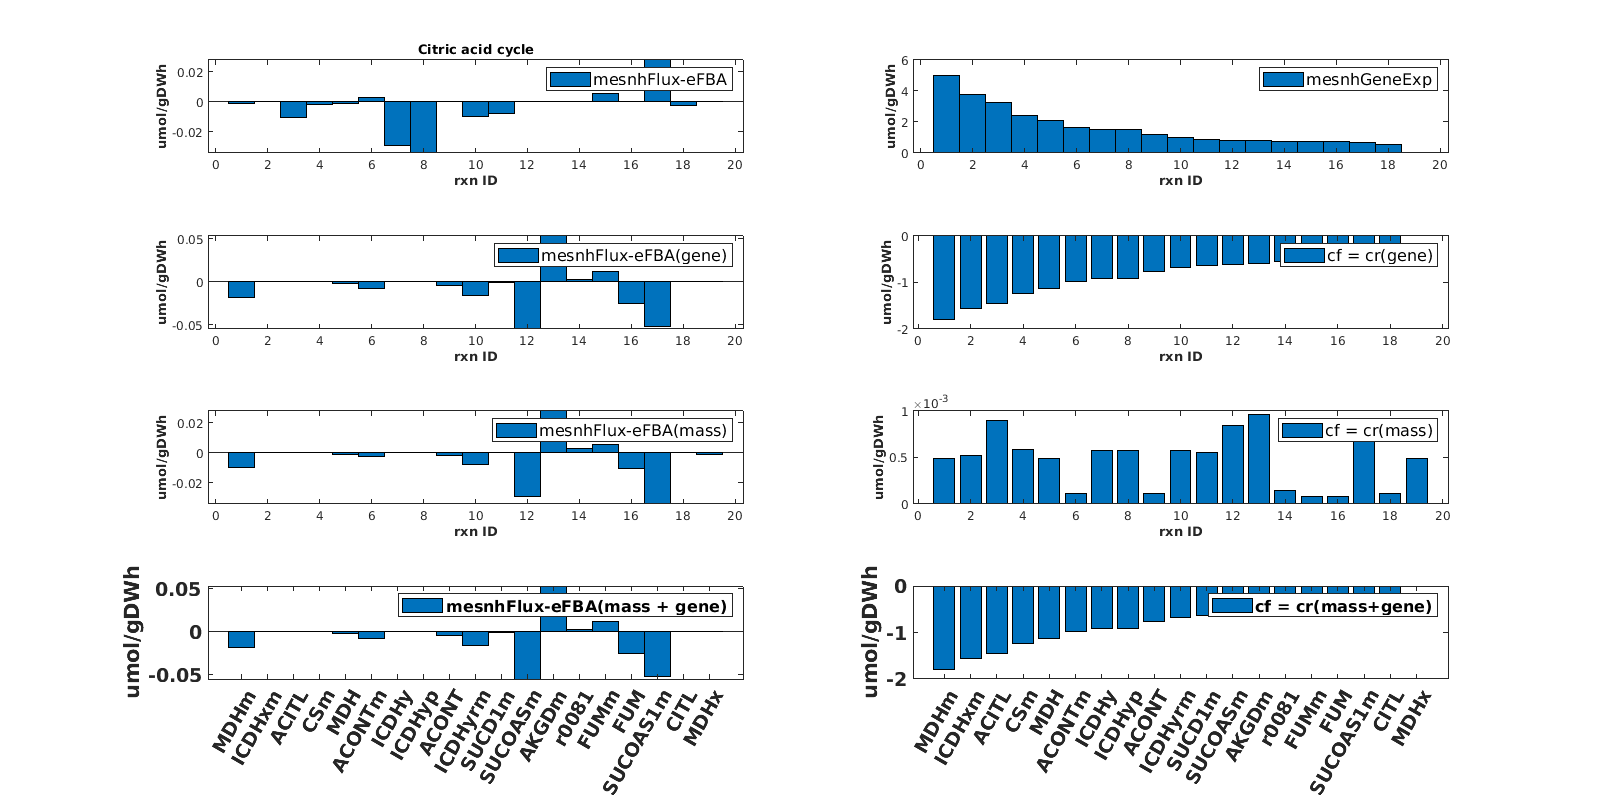

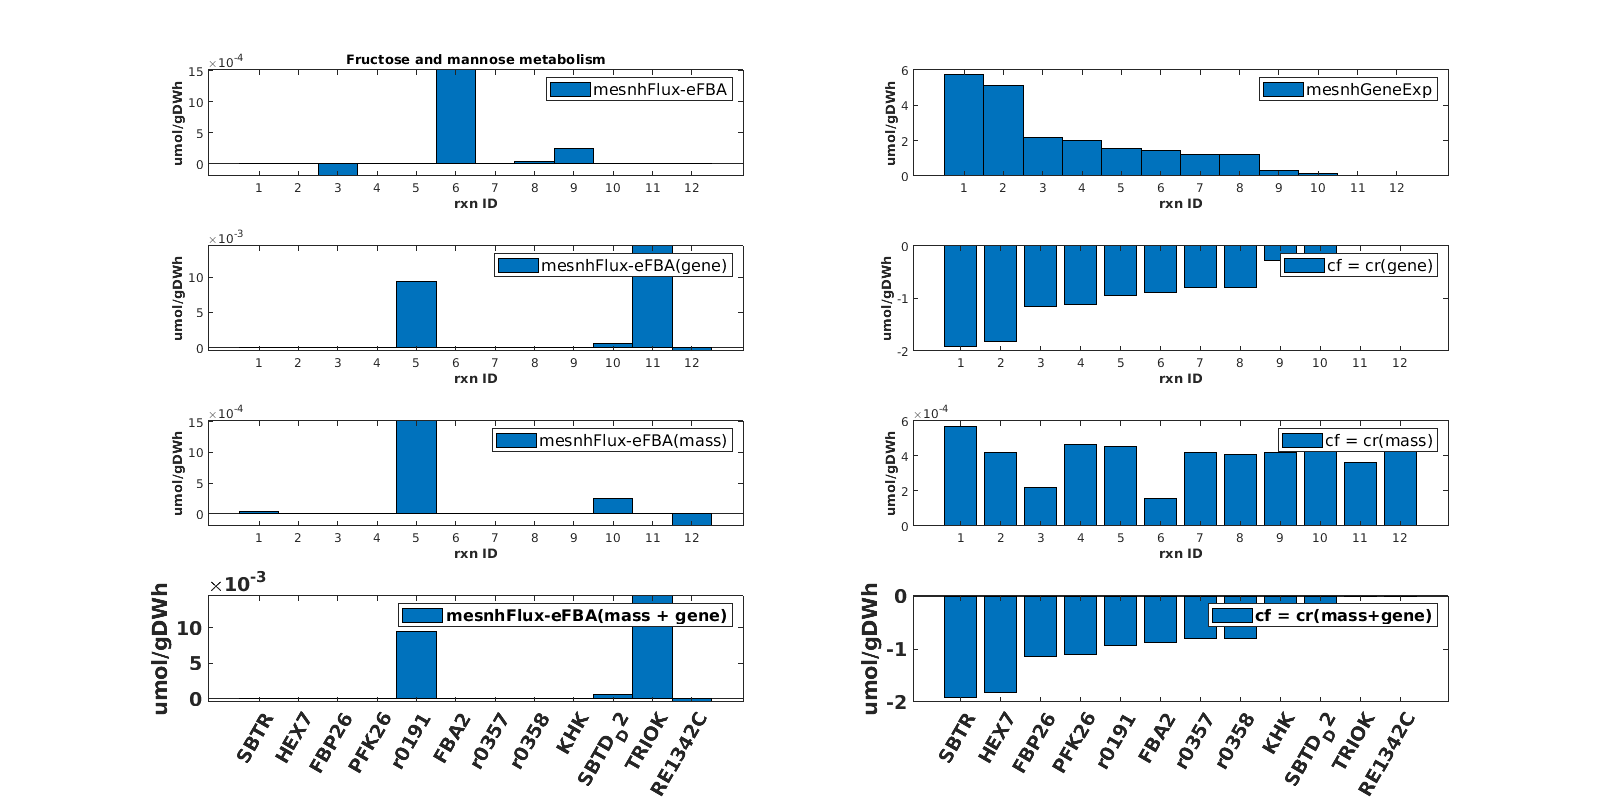

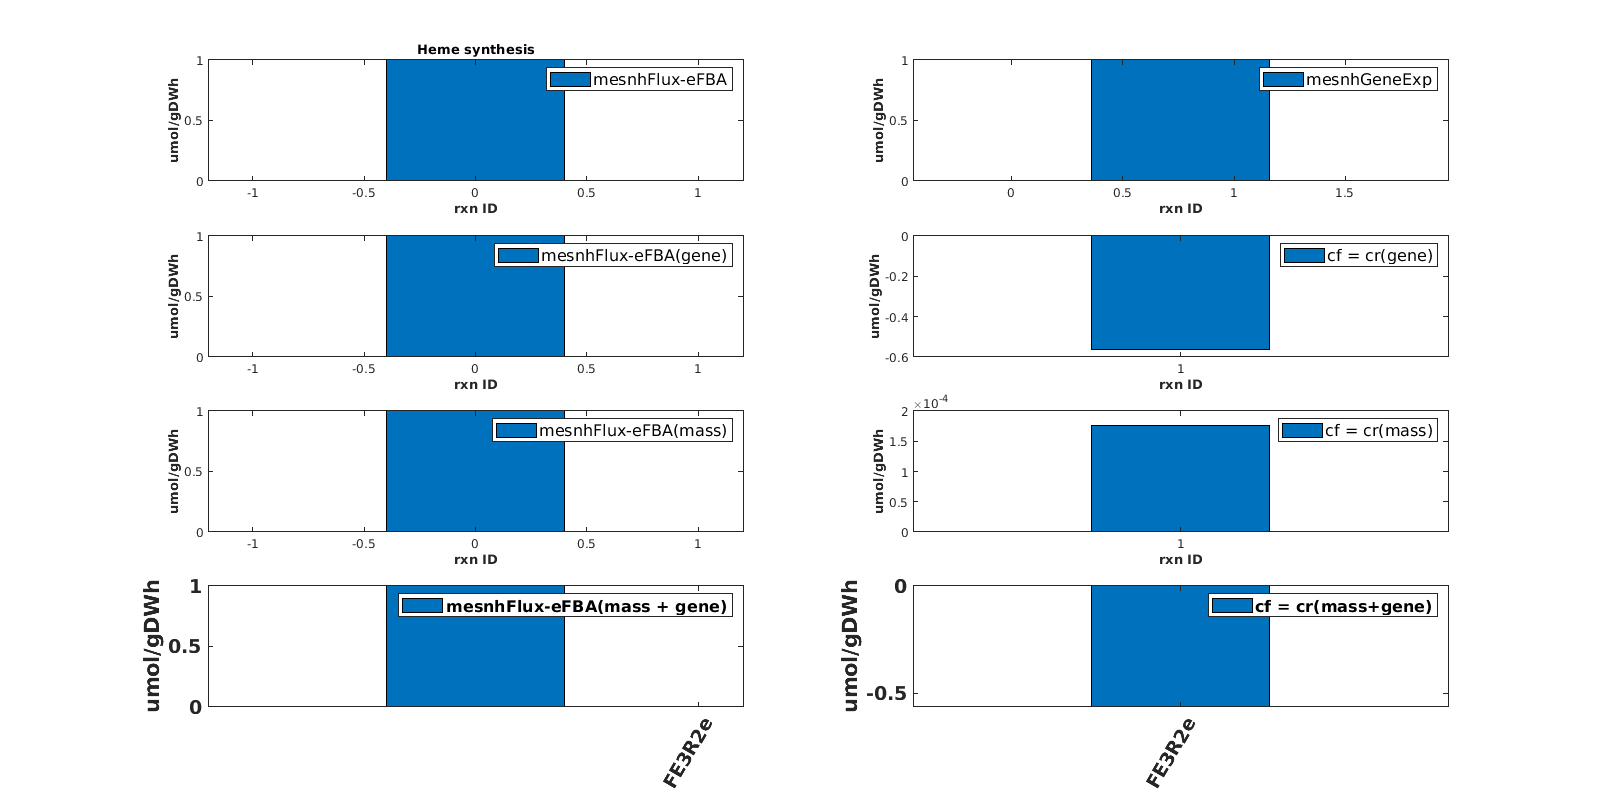

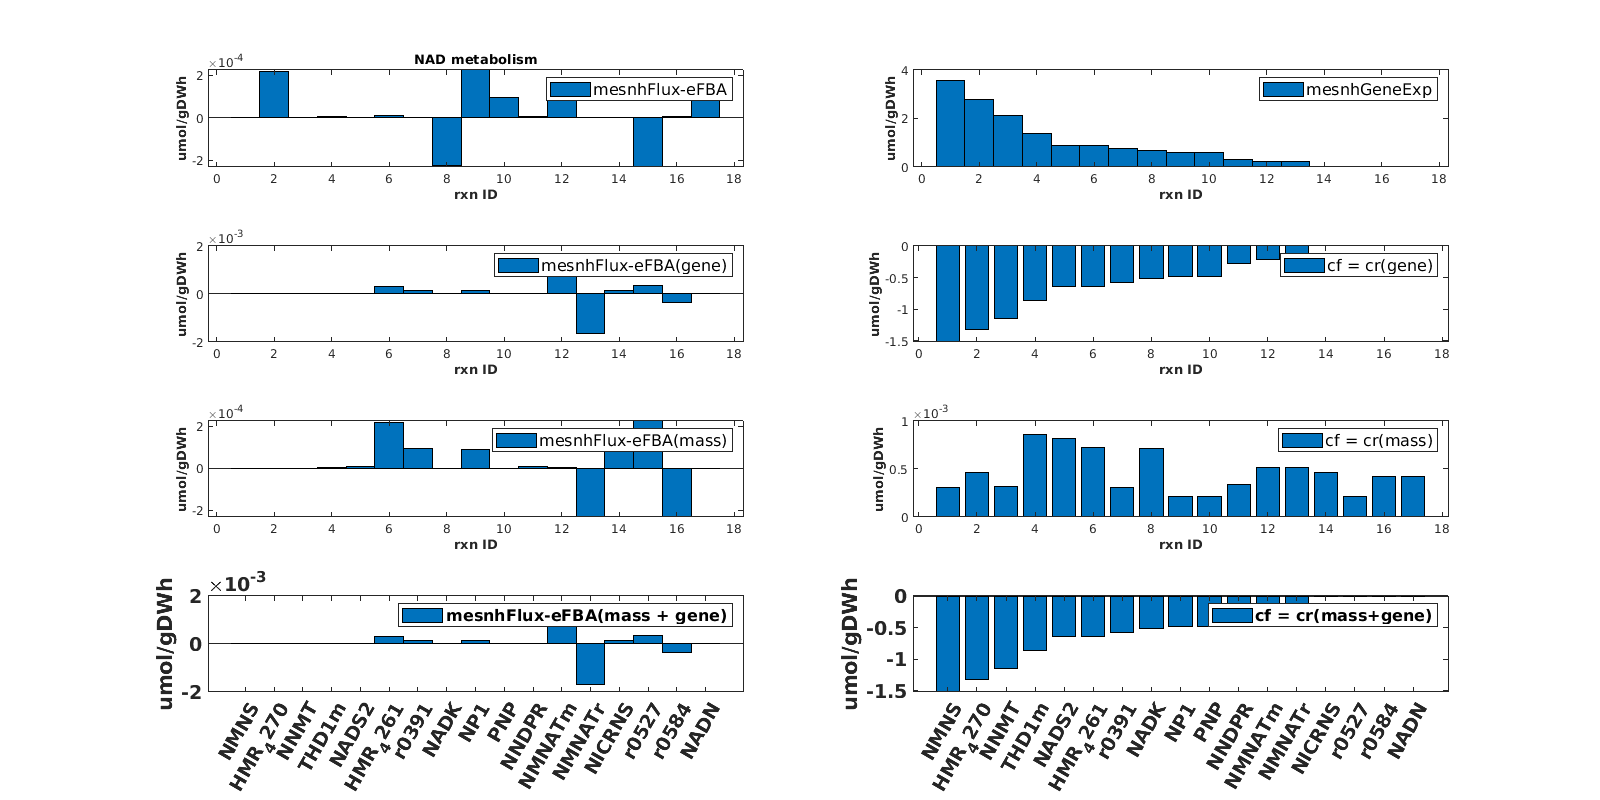

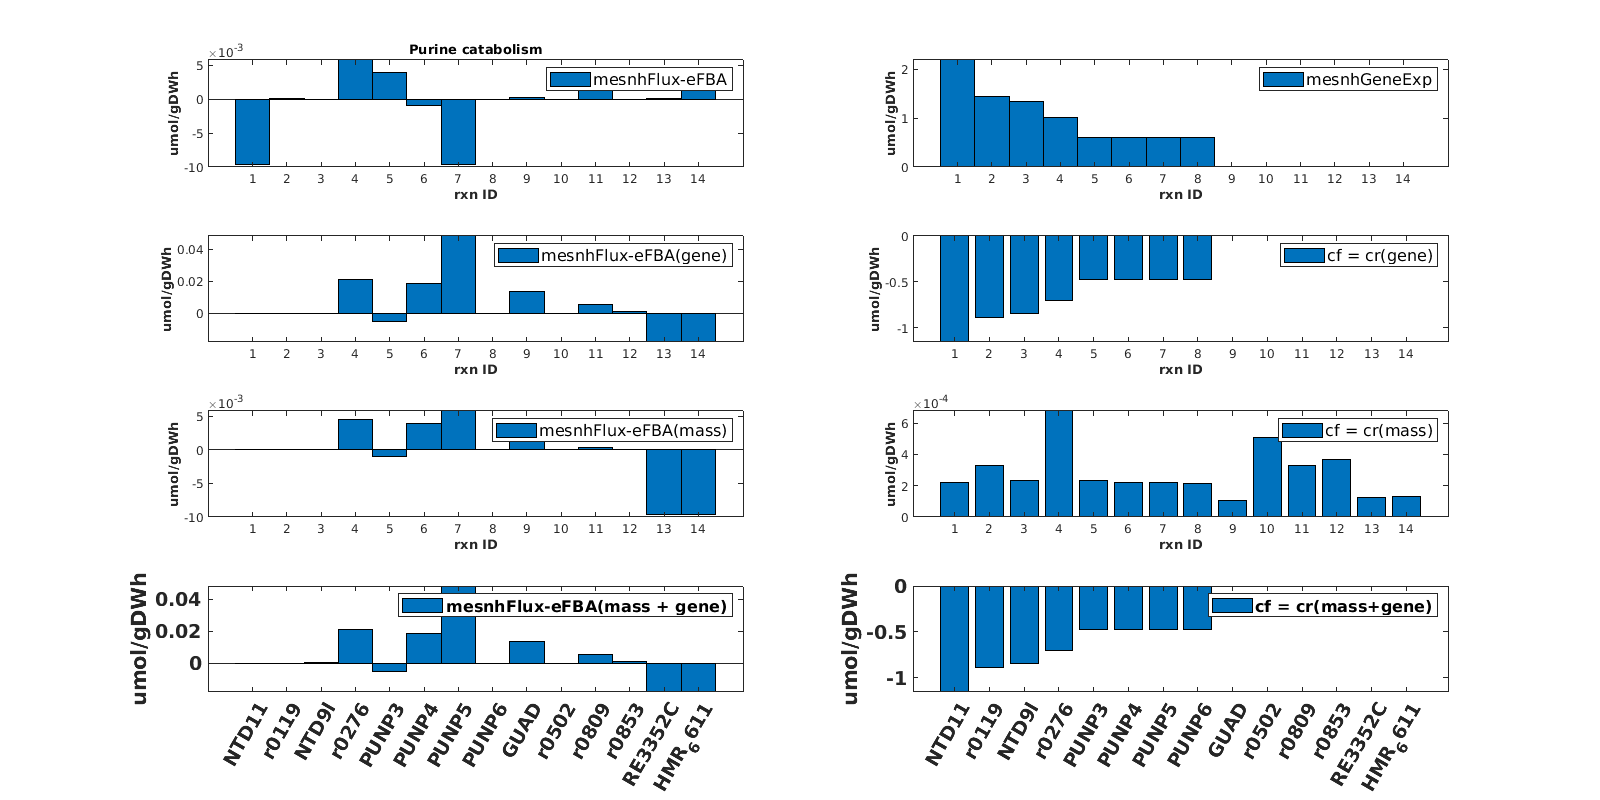

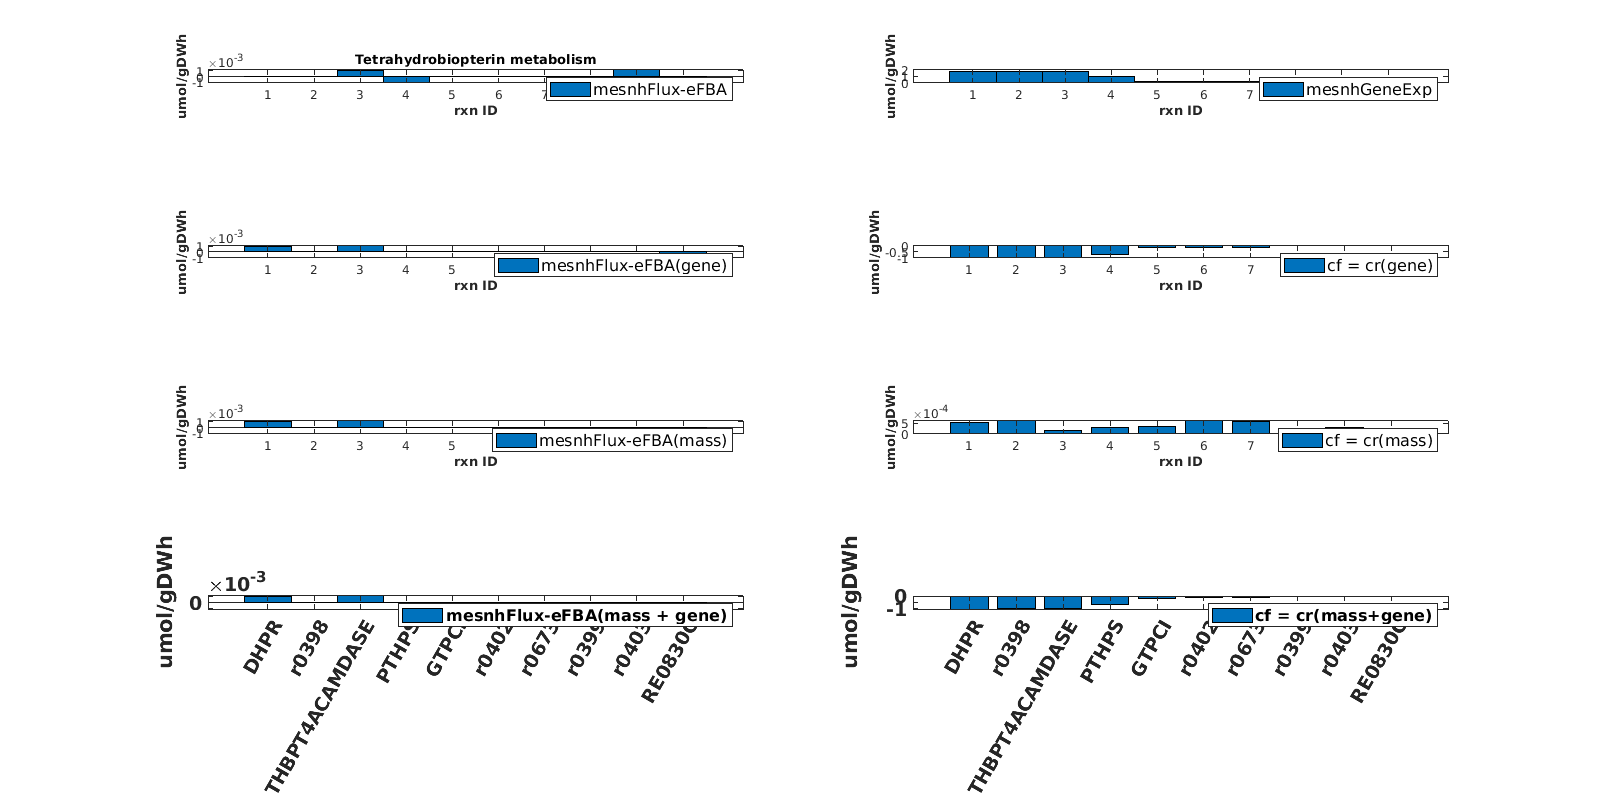

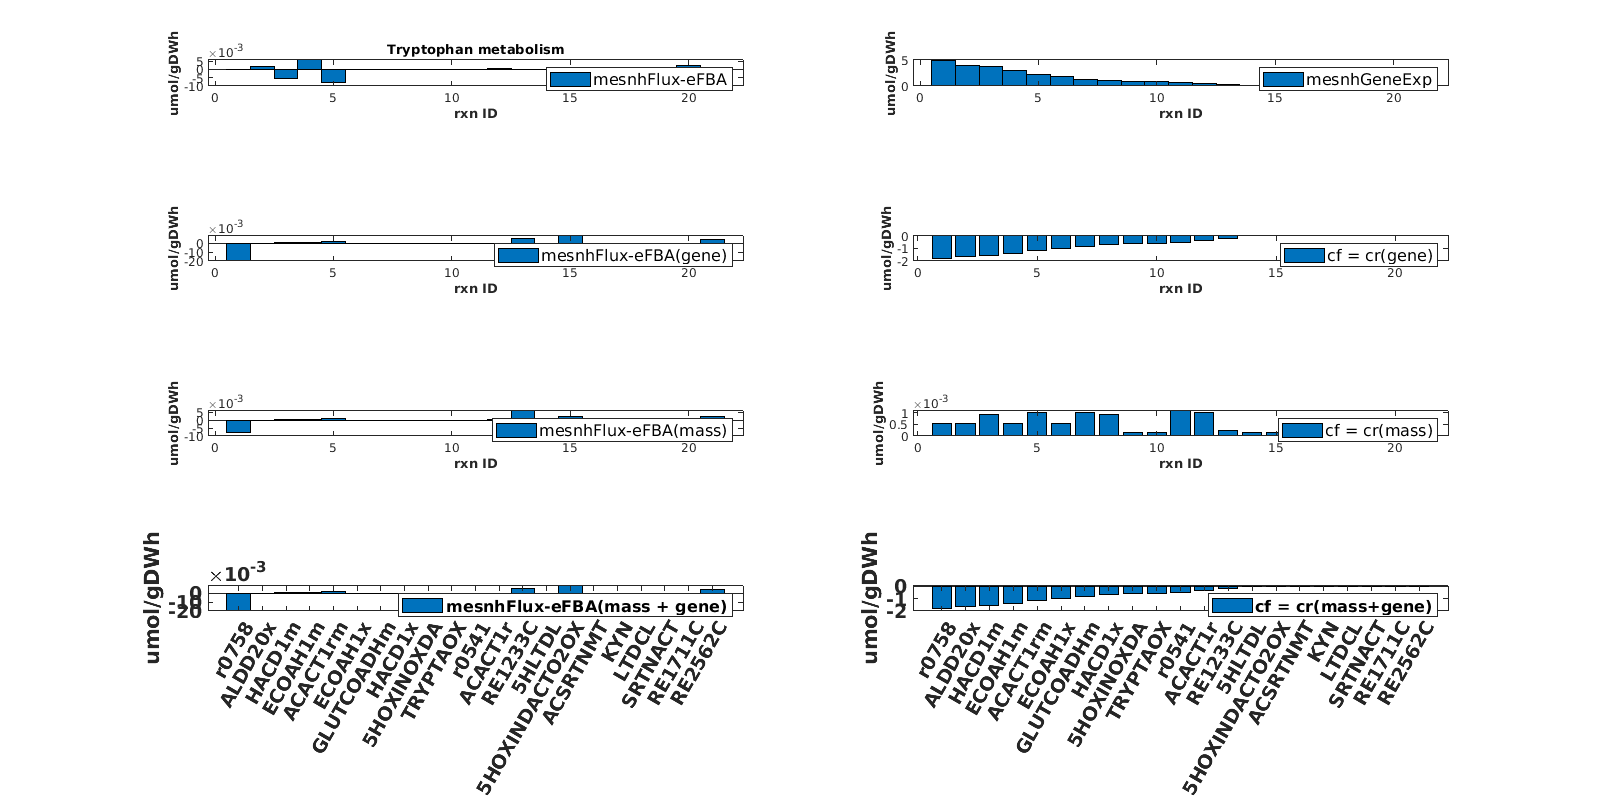

subSystem = unique(model.subSystems);

for i = 1:10:length(subSystem)

    figure('Renderer', 'painters', 'Position', [10 10 1600 800])
    ID = findRxnIDs(model,findRxnsFromSubSystem(model,subSystem(i)));
    [sortGeneWeight, idxgeneWeight] = sort(ID, 'descend');

    % findRxnsFromSubSystem(model,subSystem(i));
    %  printRxnFormula(model,model.rxns(ID))

    
    subplot(4,2,1)
    bar(solution.v(ID(idxgeneWeight)),1)
    legend('mesnhFlux-eFBA','FontSize',12)
    % set(gca,'XTick',[1:length(model.rxns(ID(contains(findRxnsFromSubSystem(model,subSystem(i)),'rec1'))))],'xticklabel',regexprep(model.rxns(ID(contains(findRxnsFromSubSystem(model,subSystem(i)),'rec2'))),'\[[^\]]*\]',''))
    % set(gca,'XTickLabelRotation',60, 'FontSize',12)
    title(char(subSystem(i)))
    xlabel('rxn ID', 'FontSize',14,'FontWeight','bold');
    ylabel('umol/gDWh', 'FontSize',14,'FontWeight','bold');

    subplot(4,2,2)
    [sortgenWeight, idxgeneWeight] = sort(SCReactionWeight(ID),'descend');
    bar(sortgenWeight,1)
    legend('mesnhGeneExp', 'FontSize',12)
    % set(gca,'XTick',[1:length(model.rxns(ID(contains(findRxnsFromSubSystem(model,subSystem(i)),'rec1'))))],'xticklabel',regexprep(model.rxns(ID(contains(findRxnsFromSubSystem(model,subSystem(i)),'rec2'))),'\[[^\]]*\]',''))
    % set(gca,'XTickLabelRotation',60, 'FontSize',12)
    xlabel('rxn ID', 'FontSize',14,'FontWeight','bold');
    ylabel('umol/gDWh', 'FontSize',14,'FontWeight','bold');

    subplot(4,2,3)
    bar(solution1.v(ID(idxgeneWeight)),1)
    legend('mesnhFlux-eFBA(gene)','FontSize',12)
    xlabel('rxn ID', 'FontSize',14,'FontWeight','bold');
    ylabel('umol/gDWh', 'FontSize',14,'FontWeight','bold');

    subplot(4,2,4)
    bar(model1.cf(ID(idxgeneWeight)))
    legend('cf = cr(gene)','FontSize',12)
    % set(gca,'XTick',[1:length(model.rxns(ID(contains(findRxnsFromSubSystem(model,subSystem(i)),'rec1'))))],'xticklabel',regexprep(model.rxns(ID(contains(findRxnsFromSubSystem(model,subSystem(i)),'rec2'))),'\[[^\]]*\]',''))
    % set(gca,'XTickLabelRotation',60, 'FontSize',12)
    % title('Gene expression in', char(subSystem(i)))
    xlabel('rxn ID', 'FontSize',14,'FontWeight','bold');
    ylabel('umol/gDWh', 'FontSize',14,'FontWeight','bold');
 
    subplot(4,2,5)
    bar(solution2.v(ID(idxgeneWeight)),1)
    legend('mesnhFlux-eFBA(mass)','FontSize',12)
    xlabel('rxn ID', 'FontSize',14,'FontWeight','bold');
    ylabel('umol/gDWh', 'FontSize',14,'FontWeight','bold');

    subplot(4,2,6)
    bar(model2.cf(ID(idxgeneWeight)))
    legend('cf = cr(mass)','FontSize',12)
    xlabel('rxn ID', 'FontSize',14,'FontWeight','bold');
    ylabel('umol/gDWh', 'FontSize',14,'FontWeight','bold');

    subplot(4,2,7)
    bar(solution3.v(ID(idxgeneWeight)),1)
    legend('mesnhFlux-eFBA(mass + gene)','FontSize',12)
    set(gca,'XTick',[1:length(model1.rxns(ID))],'xticklabel',regexprep(model1.rxns(ID(idxgeneWeight)),'\[[^\]]*\]',''))
    set(gca,'XTickLabelRotation',60, 'FontSize',14,'FontWeight','bold')
    ylabel('umol/gDWh', 'FontSize',14,'FontWeight','bold');

    subplot(4,2,8)
    bar(model3.cf(ID(idxgeneWeight)))
    legend('cf = cr(mass+gene)','FontSize',12)
    set(gca,'XTick',[1:length(model1.rxns(ID))],'xticklabel',regexprep(model1.rxns(ID(idxgeneWeight)),'\[[^\]]*\]',''))
    set(gca,'XTickLabelRotation',60, 'FontSize',14,'FontWeight','bold')
    ylabel('umol/gDWh', 'FontSize',14,'FontWeight','bold');
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
end